# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long
path_country = './testdata/COVID19/country.csv';
path_daily = './testdata/COVID19/daily_info.csv';

#### 5.3 预测分析（新增部分）

country_names = {'France','South Korea','Australia','Canada','Iceland'};
[XSeq_train, YSeq_train, ~, ~, ~, ~] = Data_Preparation(country_names,0.8,true);

test_country = {'Saudi Arabia'};
[XSeq_test_before,YSeq_test_before, XSeq_test, YSeq_test, muY, sigY] = Data_Preparation(test_country,0.9,true);

Training:

net = PredictNet(XSeq_train,YSeq_train);

Testing:

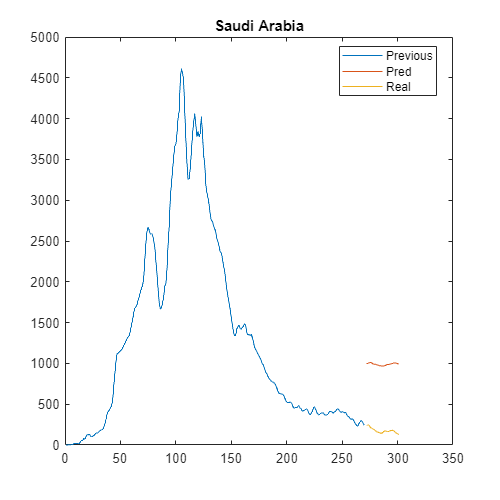

    0.8046



clf;
set(gcf,'position',[250 300 500 500])
for NUM = 1:1
Xtest = XSeq_test{NUM,1};
Ytest = YSeq_test{NUM,1};
net = resetState(net);
net = predictAndUpdateState(net,XSeq_test_before{NUM,1});
numTimeStepsTest = size(Xtest,2);
YPred = zeros(1,numTimeStepsTest);
for i = 1:numTimeStepsTest
    [net,YPred(1,i)] = predictAndUpdateState(net,Xtest(:,i),'ExecutionEnvironment','gpu');
end
relerr = norm(YPred-Ytest)/norm(Ytest);
disp(relerr)
YPred = (YPred * sigY{1,NUM}) + muY{1,NUM};
Ytest = (Ytest * sigY{1,NUM}) + muY{1,NUM};
% previous
Yprevious = (YSeq_test_before{NUM,1}*sigY{1,NUM}) + muY{1,NUM};

plot(1:size(Yprevious,2),Yprevious);
hold on;
plot(size(YSeq_train{NUM,1},2)+1:size(YSeq_train{NUM,1},2)+size(YPred,2),YPred);
plot(size(YSeq_train{NUM,1},2)+1:size(YSeq_train{NUM,1},2)+size(YPred,2),Ytest);
l = legend('Previous','Pred','Real','Location','Best');
title(test_country{1,NUM});

end

% Regression Net
country_names = {'France','South Korea','Australia','Canada','Iceland','China','Ethiopia','Zimbabwe'};
[XSeq_train, YSeq_train, ~, ~, ~, ~] = Data_Preparation(country_names,1,true);

test_country = {'Saudi Arabia','Germany','Japan','United States'};
[XSeq_test, YSeq_test, ~, ~, muY, sigY] = Data_Preparation(test_country,1,true);

Training

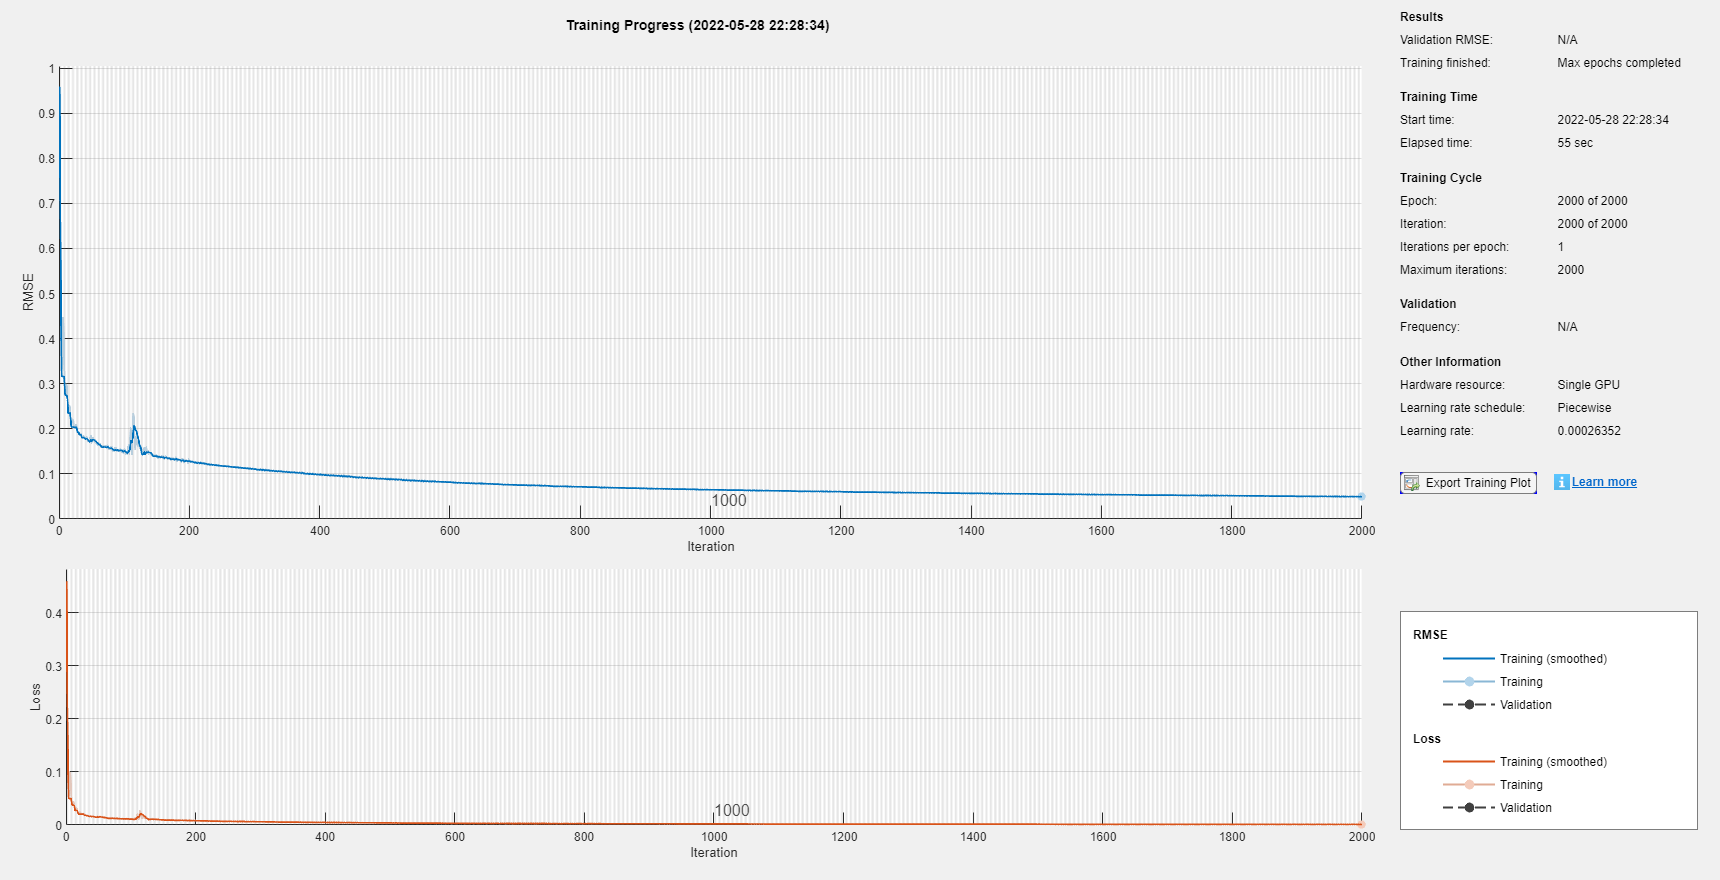

net = RegressionNet(XSeq_train,YSeq_train);

Testing

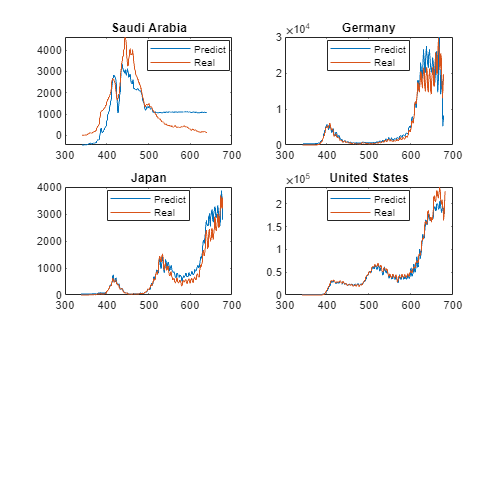

    0.5728

    0.3065

    0.2993

    0.1291



clf;
set(gcf,'position',[250 300 500 500])
for NUM = 1:size(test_country,2)
Xtest = XSeq_test{NUM,1};
Ytest = YSeq_test{NUM,1};
net = resetState(net);
numTimeStepsTest = size(Xtest,2);
YPred = zeros(1,numTimeStepsTest);
for i = 1:numTimeStepsTest
    [net,YPred(1,i)] = predictAndUpdateState(net,Xtest(:,i),'ExecutionEnvironment','gpu');
end
relerr = norm(YPred-Ytest)/norm(Ytest);
disp(relerr)
YPred = (YPred * sigY{1,NUM}) + muY{1,NUM};
Ytest = (Ytest * sigY{1,NUM}) + muY{1,NUM};

subplot(3,2,NUM);
plot(size(YSeq_train{NUM,1},2)+1:size(YSeq_train{NUM,1},2)+size(YPred,2),YPred);
hold on;
plot(size(YSeq_train{NUM,1},2)+1:size(YSeq_train{NUM,1},2)+size(YPred,2),Ytest);
l = legend('Predict','Real','Location','Best');
title(test_country{1,NUM});
end